%%Example for PCA
%PCA uses singular value decomposition (svd) to find scores and loadings
%Define Infrared data as x
X = table2array(IRData(:,2))

X =    1.270072000000000   1.273169000000000   1.266092500000000   1.258869500000000   1.251778000000000   1.245674000000000   1.236025000000000   1.223376000000000   1.208249000000000   1.192674500000000   1.175959500000000   1.160291000000000   1.144489500000000   1.126984500000000   1.105507500000000   1.083068000000000   1.063748000000000   1.049149000000000   1.034143000000000   1.011778500000000   0.977882000000000   0.931103000000000   0.869736500000000   0.790495500000000   0.689534500000000   0.562371000000000   0.409401500000000   0.251331000000000   0.131182000000000   0.086256000000000   0.132777500000000   0.254543500000000   0.403495000000000   0.523626000000000   0.587334500000000   0.595856500000000   0.561839500000000   0.501582000000000   0.437757000000000   0.399591500000000   0.413469500000000   0.482412500000000   0.580732500000000   0.674243000000000   0.743789500000000   0.788166000000000   0.815461000000000   0.834572500000000   0.851212000000000   0.86773450000

%Scale the data
Xs=X*inv(diag(std(X)))

Xs = 	1.0e+02 *

   0.959795854704045   0.989254945269785   0.998366762057573   1.043062408837399   1.102923197728012   1.149319740017764   1.190775493266806   1.223718778140832   1.263433384693060   1.321455671670226   1.384649648201994   1.403994528132645   1.386262525522532   1.343601876683357   1.283560860225906   1.222136712356187   1.198356507011263   1.215125253544182   1.212219781709032   1.134294280635662   1.006851082440596   0.874802098258545   0.745840861392052   0.618694798994050   0.496468215750131   0.385019149447788   0.290838922799106   0.215109712134190   0.156376287876020   0.126812054659581   0.156212141373792   0.213415323843284   0.277498657577961   0.333757550522270   0.367830204179990   0.376488028140379   0.362463363738303   0.331956845075827   0.298275899986759   0.279113679288995   0.291925233226365   0.342092334948880   0.415506384147336   0.482260222930553   0.526432465176222   0.561577150309434   0.604073553185072   0.663152197579520   0.743935285088379   

%Scores loadings
[U,D,Loadings]=svd(Xs)

U =   -0.150698203051730  -0.107264072743950   0.047132400121503  -0.075840306419083   0.110048139114043  -0.321478377449618  -0.004895373250087   0.028843018540486   0.404106195749139   0.134006183074693  -0.301110216774305   0.187201173814254  -0.166833377846884   0.131139301021639  -0.070621806274664   0.197725957449220  -0.146319376481287   0.094440679282954  -0.071441230931895  -0.156938059676987   0.209995076052970   0.031691758955377   0.096075545069547  -0.158485760952995  -0.010798444238254  -0.148634174246106  -0.133049558119942  -0.076354252577771  -0.023037331521613   0.275395683226082   0.045758919141603   0.010923809573228   0.104141490153583   0.082095897153335   0.292805912417191   0.005077953731874   0.106686902182770  -0.135748973774690  -0.048936834305157  -0.023089836877206  -0.064640914469650  -0.188009888718498  -0.028202351470104  -0.071873772585549
  -0.150228701517188   0.053962289751662  -0.068985167801068  -0.064741138209403   0.098905562315286  -0.0889713495

D = 	1.0e+04 *

   1.838450292653167                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0    

Loadings =   -0.035134023011958   0.059917898317343  -0.068563933600929   0.035845085573551   0.038438450195808   0.008864954159610   0.080880931115066  -0.195614218421290  -0.066221577550261   0.078355206993741   0.039057929976672   0.029504511719933   0.078407589438687  -0.009693198307710  -0.201292470946722  -0.104329840759177   0.054790519809269  -0.053964460268931   0.112124183398822   0.373636726660967  -0.253117478012637  -0.327460243836615   0.065533527679909  -0.336023040191613   0.062072885173289  -0.035292182327600   0.313679045911827   0.085774382205967   0.154970137459027  -0.083775264130415  -0.158500434597540   0.082144530852350  -0.001269407249544   0.215851006104076   0.048550334608384   0.001263957255079  -0.059328350393628  -0.043551455585004   0.158435092733575   0.011656334826770   0.035392590961526   0.075531323545828   0.043523389708008   0.044693532784553  -0.021332378937714  -0.010918711657927  -0.012883769845157  -0.016504004083584  -0.018576567624240  -0.0184

Scores = U*D

Scores = 	1.0e+03 *

  -2.770511555027602  -0.009403256247678   0.003422971921778  -0.002100319693565   0.002177686869753  -0.005312565908913  -0.000067250244041   0.000225703426516   0.002935120821018   0.000736022219598  -0.001333673345895   0.000819000481200  -0.000659614938489   0.000500277727189  -0.000222526283088   0.000571780900439  -0.000358343662015   0.000215936903776  -0.000137184890653  -0.000276177992706   0.000339798632531   0.000047587622759   0.000134675248370  -0.000195511487775  -0.000012678849419  -0.000165650077853  -0.000130023496942  -0.000068901869056  -0.000019473275484   0.000217765481307   0.000034921639077   0.000007566454582   0.000065979770417   0.000048535325611   0.000153488550761   0.000002556385510   0.000050424687289  -0.000057473560651  -0.000019562400801  -0.000008541946098  -0.000021759487221  -0.000060945370904  -0.000008754793510  -0.000019331750327                   0                   0                   0                   0                   

%This line of code joins the label of the wine to the score values
Scores = [{Label_Wine_samples}, {Scores}]

Scores = 1×2 cell array
    {44×1 categorical}    {44×842 double}


%Obtain the score values for the Argentinian wines
ARG=Scores{:,2}(Scores{:,1}=='ARG',[2,4])

ARG =   -9.403256247677842  -2.100319693564768
   4.730579636460221  -1.792939585629006
  -4.460635665662594  -3.943616854861468
   8.967790253955451  -5.567209518107902
  10.460157981809216  -2.384110797273692
  11.811018648628760  -0.298910521749876


scatter(ARG(:,1),ARG(:,2),'red')
hold on 
AUS=Scores{:,2}(Scores{:,1}=='AUS',[2,4])

AUS =    3.692616531808804   0.961308475846085
  14.749797238482339  -4.934396301767368
 -10.303018966176035  -3.652661970911418
  16.052734315778665   4.734496270867246
  25.425517571308291   4.440018198298238
   1.596785779708096  -5.711782115471203
  -3.126095898196345  10.117147211550119
  -6.616535129866014   2.732535570275876
  31.594569119611648  -4.008791373806589
 -12.322031895527815   8.766975022095599


scatter(AUS(:,1),AUS(:,2),'black')
hold on
CHI=Scores{:,2}(Scores{:,1}=='CHI',[2,4])

CHI =   -2.267278748425723  -0.615181131005889
 -28.517794981815708  -1.034181461799587
   0.140396499352555  -1.373733062042051
   2.310137195336006   0.065453634656402
  -9.221967719403660  -5.652804818320596
   2.029116881610865  -0.352119005816197
 -11.556484746116315  -2.784493341929126
 -13.865042847807777  -1.583695668645043
 -25.784787924737959   0.039818846082956
 -10.070337376249219  -5.635517849037511


scatter(CHI(:,1),CHI(:,2),'blue')
hold on
SOU=Scores{:,2}(Scores{:,1}=='SOU',[2,4])

SOU =    1.576456853936227  12.061644279205995
   1.211312122945169  -0.205441155622776
   1.883512181798587   1.894190999452851
   2.029558864715550   7.420597668655011
  14.837423052951818   4.630415161902643
   2.282481427789088   1.179083128511736
   6.074692420826639   3.648473468976626
  -0.047308065853522  -2.375457506000750
  17.950180453194484  -3.249303154666181
  15.517374566270929  -0.478493811137143


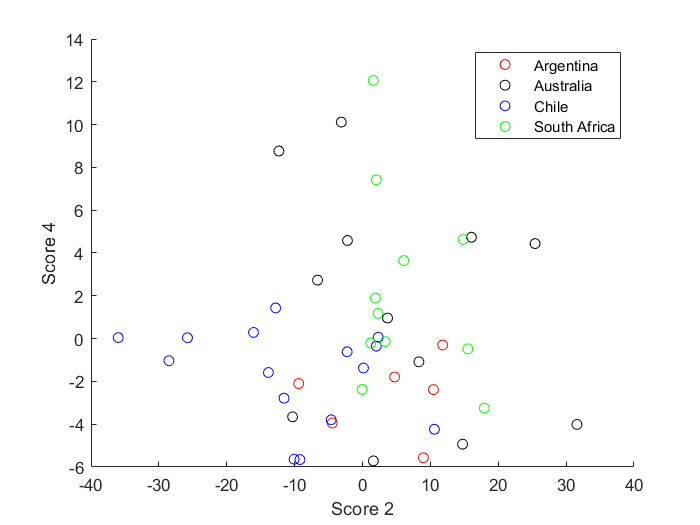

scatter(SOU(:,1),SOU(:,2),'green')
legend({'Argentina';'Australia';'Chile';'South Africa'})
xlabel('Score 2')
ylabel('Score 4')
hold off

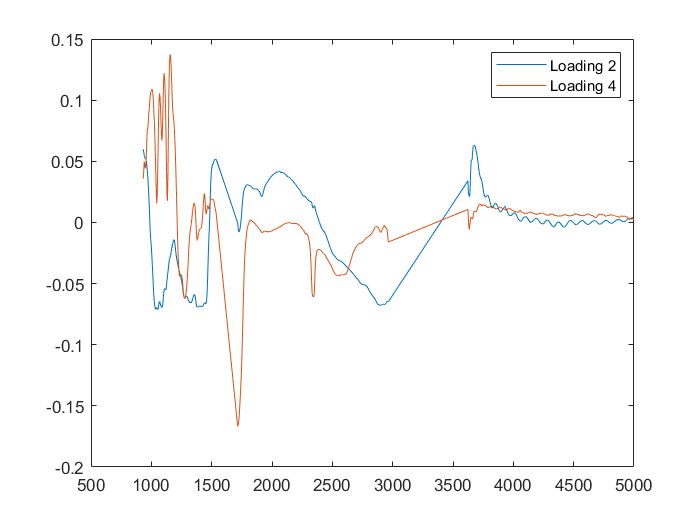


plot(axis_spectra_wavenumber,[Loadings(:,2),Loadings(:,4)])
legend({'Loading 2'; 'Loading 4'})